clear all;clc;
x = [1,1];

**Question 3. Nonlinear optimisation — quadratic programming.**

**(a) Consider the minimisation of the objective function**


$$f\left(x,y\right)=2x^2 +5y^2 -2\mathrm{xy}-2x-8y$$


     **of two unconstrained variables x and y.**

    (i) Working by hand. Freeze $x=0$, and find the location$y^*$ of the minimum of the function $f\left(0,y\right)$ of one variable y. Then freeze $y=y^*$ and find the location $x^*$ of the minimum of the function $f\left(x,y^* \right)$ of one variable x.

(3 marks)

   Deriving the value of $y^*$:


$$x=0$$



$$f\left(0,y\right)=2{\left(0\right)}^2 +5y^2 -2\left(0\right)y-2\left(0\right)-8y$$



$$f\left(0,y\right)=5y^2 -8y$$



$$\frac{\mathrm{d}}{\mathrm{d}y}f=0=10y^* -8$$



$$10y^* =8$$



$$y^* =0\ldotp 8$$


minimum = $\left(0,0\ldotp 8\right)$

Substituing $y^* \;\textrm{to}\;\textrm{attain}\;x^*$


$$f\left(x,y^* \right)=f\left(x,0\ldotp 8\right)=2x^2 +5{\left(0\ldotp 8\right)}^2 -2x\left(0\ldotp 8\right)-2x-8\left(0\ldotp 8\right)$$



$$f\left(x,y^* \right)=2x^2 -1\ldotp 6x-3\ldotp 2$$



$$\frac{\mathrm{d}}{\mathrm{d}x}f=0=4x^* -1\ldotp 6$$



$$4x^* =1\ldotp 6$$



$$x^* =0\ldotp 4$$


minmum = (0.4, 0.8)

    (ii) Working by hand. Find ∇f . Thus, beginning from the origin (0, 0), perform one step of the steepest-descent algorithm. That, is find the λ(1) such that the function (0, 0)T + λ∇f (0, 0) of one variable λ is minimised, and find the corresponding coordinates of the next iterate (x(1), y(1)).$$

(4 marks)


$$f\left(x,y\right)=2x^2 +5y^2 -2\mathrm{xy}-2x-8y$$



$$\nabla f\left(x,y\right)=\left(4x-2y-2,\;10y-2x-8\right)$$


Thus:


$$\nabla f\left(x^0 ,y^0 \right)=\left(4\left(0\right)-2\left(0\right)-2,\;10\left(0\right)-2\left(0\right)-8\right)$$



$$\nabla f\left(x^0 ,y^0 \right)=\left(-2,-8\right)$$


for $x^0 ,y^0 =\left(0,0\right)$. So: 


$$\begin{array}{l}
f\left\lbrack \left(x^0 ,y^0 \right)+\lambda \nabla f\left(x^0 ,y^0 \right)\right\rbrack =\min \;f\left\lbrack \left(0,0\right)+\lambda \left(-2,-8\right)\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\min \;f\left\lbrack -2\lambda ,-8\lambda \right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\min \;\left\lbrack 8\lambda^2 +320\lambda^2 -32\lambda^2 +4\lambda +64\lambda \right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\min \;\left\lbrack 296\lambda^2 +68\lambda \right\rbrack 
\end{array}$$


The optimal value of $\lambda$ is found from:


$$\frac{\mathrm{d}}{\mathrm{d}\lambda }\left(296\lambda^2 +68\lambda \right)=592\lambda +68=0$$


thus:


$$\lambda^* =-\frac{17}{148}$$


so:


$$x_{1\;} ,y_1 =x_0 ,y_0 +\lambda \nabla f\left(x_0 ,y_0 \right)=\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack +-\frac{17}{148}\left\lbrack \begin{array}{c}
-2\\
-8
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{17}{74}\\
\frac{34}{37}
\end{array}\right\rbrack \;$$



$$\mathrm{Iteration}\;1\;\mathrm{of}\;\mathrm{steepest}\;\mathrm{descent}\;\left(\mathrm{SD}\right):\left(x^1 ,y^1 \right)=\left(\frac{17}{74},\frac{34}{37}\right)$$


**3.1.3    (iii) Develop, exhibit, and explain quadprog code that finds the minimum value and the location of the minimum of f (x, y).**


$$f\left(x,y\right)=2x^2 +5y^2 -2\textrm{xy}-2x-8y$$


% Define Hessian and function matrices
H = [4 -2;
    -2 10];
f = [-2; 
     -8];
[x, fval] = quadprog(H, f);

fprintf('The location of minimum is (%.2f, %.2f)', x(1), x(2))

The location of minimum is (1.00, 1.00)

**3.1.4  (iv) Use your favourite package to plot (e.g., contours) of f (x, y) in the quadrant x1, x2 ≥ 0 and overlay points and lines corresponding to your part (i-iii) computations and discuss. Sketch on your plot how a second iteration of the steepest-descent algorithm would proceed.**

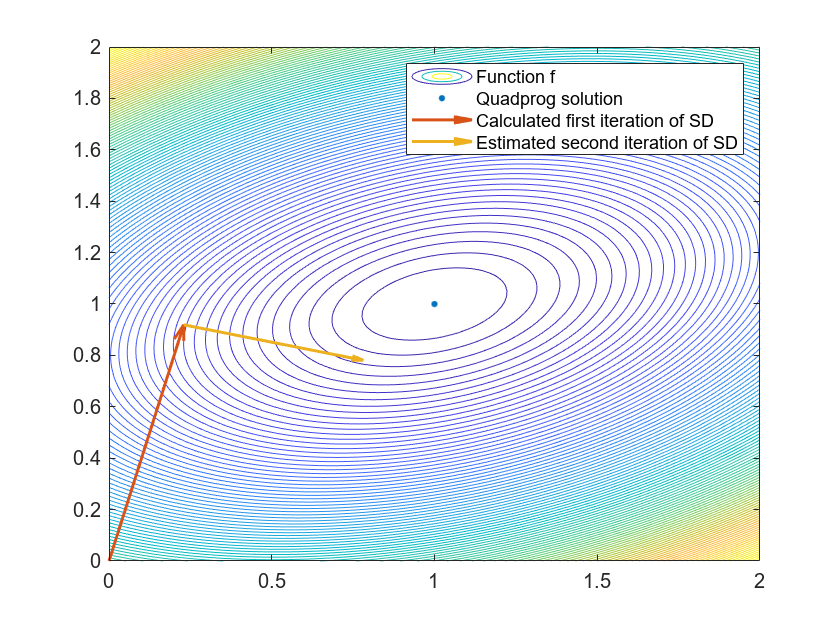

fun = @(x,y)2.*x.^2 + 5.*y.^2 -2.*x.*y -2.*x -8.*y;
xy1 = [17/74 34/37];

contourPlot = functions.plotContour(fun,x, xy1);

**3.2 Part b.**

** Study the codes provided with Q2 of lab sheet 04 to study resistor networks. For the purposes of this assignment, you may use the provided function Kirchoffsolve.m as a tool without understanding or explaining any of its contents. Your task is to study the effective resistance of a resistor network, whose junctions are at positive integer ‘square lattice’ positions **$\left(\mathit{\mathbf{i}},\mathit{\mathbf{j}}\right),\mathit{\mathbf{i}},\mathit{\mathbf{j}}=1,2,\ldotp \ldotp \ldotp ,\mathit{\mathbf{N}}$** , where **$\mathit{\mathbf{N}}\ge 2$** is an integer parameter. The anode and cathode are the nodes at **$\left(1,1\right)$** and **$\left(\mathit{\mathbf{N}},\mathit{\mathbf{N}}\right)$** respectively. Each resistor is ohmic with resistance 1 ohm, and they connect adjacent nodes in a square lattice ‘Manhattan’ network.**

**Develop, exhibit, and explain code (e.g., write a new NetworkPreparation.m and then call Kirchoffsolve.m) to study the effective resistance of this network as N increases. Explore how big you can make N before your computer struggles**

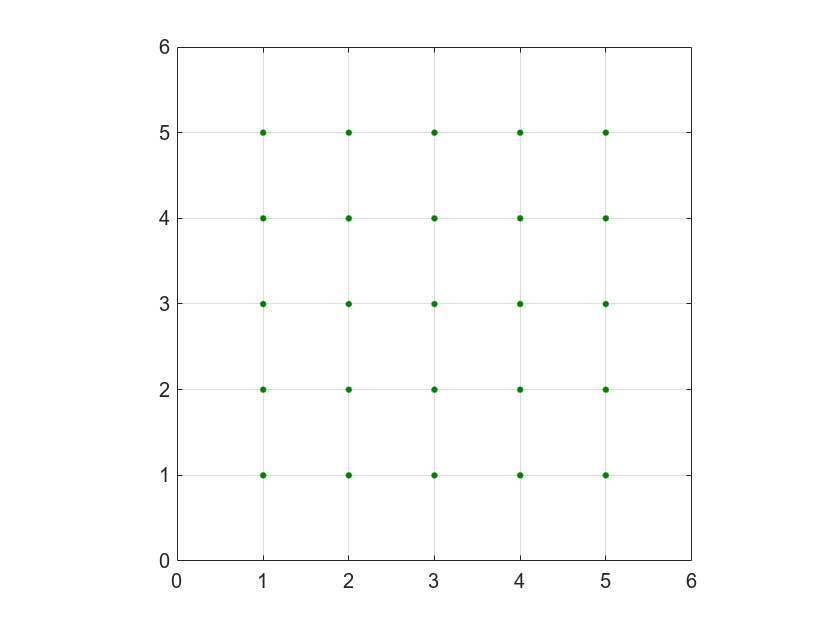

N = 5;

% First step is construct the network of nodes for a predefined 'N' variable
x = (1:N)';
x = repmat(x, [N, 1]);
y = ones(N, 1);
for i = 2:N
    col = i*ones(N,1);
    y = [y;col];
end
fig = functions.plotNodes(x, y);

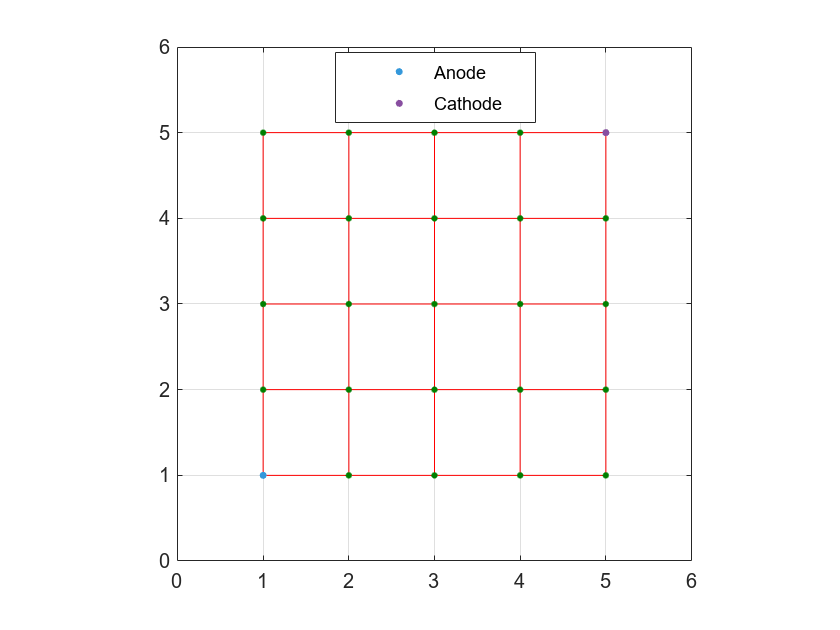

% From the nodes, the edges can be defined
numResistors = 2*N^2 - 2*N;
st = zeros(numResistors, 2);

rowI = 1;
elementI = 1;
for yi = 1:N
    for xi = 1:N
        % Edge nodes have one less connection
        if yi ~= N
            st(rowI,:) = [elementI, elementI+N];
            rowI = rowI + 1;
        end
        if xi ~= N
            st(rowI,:) = [elementI, elementI+1];
            rowI = rowI + 1;
        end
        elementI = elementI + 1;
    end
end

% Define Anode and Cathode indices as bottom left and top right values
listAnode=1; listCnode=N^2;

fig = functions.plotResistors(x, y, st);

% Define resistor values as 1 ohm
r = ones(numResistors, 1);

% Apply Kirchoff solver. Solver assumes total current flow of 1 Amp.
[X,V]=KirchoffSolve(st,r,listAnode,listCnode);

____________________________________________________________
   Diagnostic Information

Number of variables: 42

 
Number of linear inequality constraints:    0
Number of linear equality constraints:      27
Number of lower bound constraints:          0
Number of upper bound constraints:          0

Algorithm selected
   interior-point-convex


____________________________________________________________
   End diagnostic information

 Iter            Fval  Primal Infeas    Dual Infeas  Complementarity  
    0    2.000000e+01   1.000000e+00   9.090909e-01     0.000000e+00  
    1    1.068182e+00   4.440892e-16   3.330669e-16     0.000000e+00  

Optimization completed: The relative dual feasibility, 3.330669e-16,
is less than options.OptimalityTolerance = 1.000000e-08, the 

% Calculate voltage drop
Vdrop = V(listCnode(1))-V(listAnode(1));

% Since the total current equals 1 Amp, resistance equals Vdrop
effectiveResistance = Vdrop

effectiveResistance = 2.1364

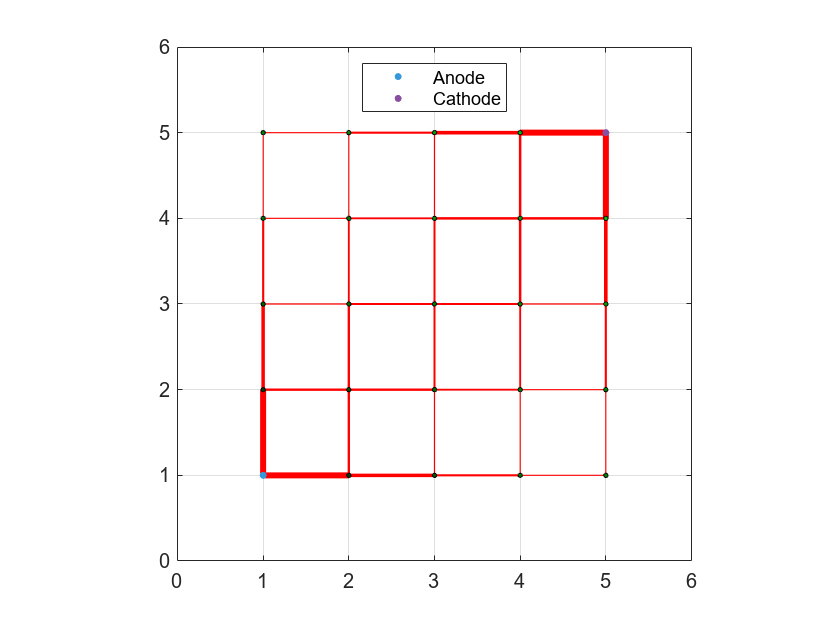

% Plotting the results:
fig = functions.plotNetwork(x, y, st, X, V);

All of the code above has been bundled up into a function

Vdrop = manhattanNetwork(N)

The same function has been called for values of N ranging from 2 to 1000 and the results can be seen in the table below:

Table = getTable;
disp(Table)

     N     Resistance (Ohm)    Time (s)
    ___    ________________    ________

      2              1          0.0453 
      5         2.1364          0.0094 
     10         3.0117          0.0096 
     20         3.8923          0.0251 
     50         5.0584          0.0613 
    100         5.9408          0.2089 
    200         6.8234          2.0277 
    300         7.3396           9.263 
    400         7.7059          34.197 
    500           7.99          90.184 
    600         8.2221          230.23 
    700         8.4184          475.59 



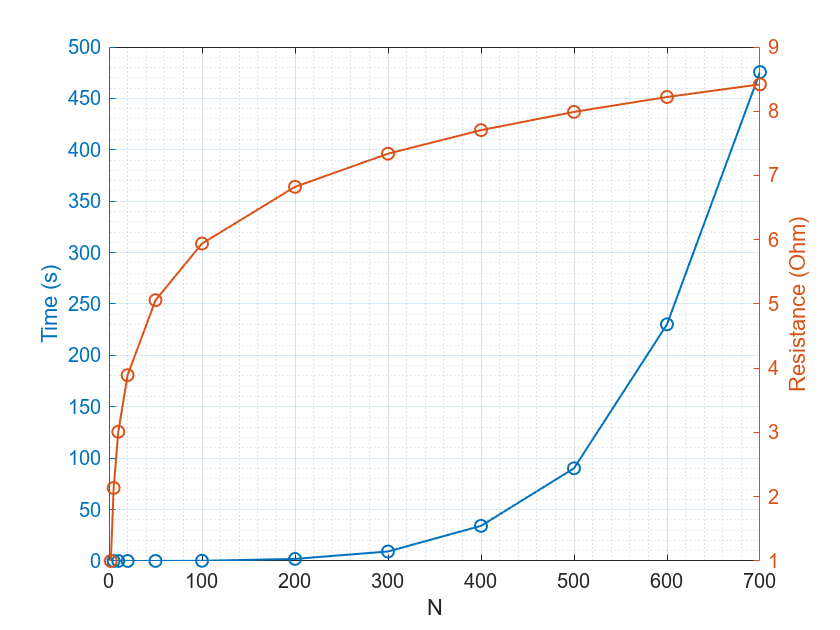

% Plotting these values
fig = functions.plotResistance(Table);

The resistance behaves in respect to log(N) whereas the time responds inversely to the exponential of N. By the time N = 700, the time taken to compute is over 8 minutes.